## Prueba Corta Final

## MA-1006 Segundo Ciclo 2023

## Introduccion al Analisis Numerico

- Nombre completo: Josef Ruzicka    

- Carnet: B87095

**Intrucciones: **La resolución debe hacerse en este archivo.mlx. Utilice los archivos de ODE.mlx, el cual se encuentra en Mediacion Virtual. Verifique que los códigos, programas y funciones se ejecuten correctamente antes de entregar este archivo **mediación virtual **antes de las 11:59 a.m. del martes 28 de noviembre de 2023. Luego de ese límite de tiempo no habrá chance de entrega. El valor porcentual de esta prueba es de 10%, en formato individual. 

## Problema #1. (10 puntos, 5%)

Considere el problema de valor inicial $y' = 1 + (t-y)^2, \quad y(2) = 1,$ en el intervalo $[a,\, b] = [2, \, 3].$ Se sabe que la solución exacta es $y(t) = t + \frac{1}{1 - t}$. Considere la particion uniforme $T = \{t_k \}_{k=0}^5$, en donde $t_k = 2 + k h$, donde $h = \frac{1}{5}$.

- (2 pts) Utilice el metodo de Heun para producir los nodos $(t_k, y_k^{Heun})$

- (2 pts) Utilice el metodo PC4 para producir los nodos $(t_k, y_k^{PC4})$

- (3 pts) Determine los polinomios de interpolacion para los nodos de Heun y PC4 anteriores.

- (3 pts) Grafique en conjunto la solucion exacta del PVI, y los polinomios de interpolacion del punto 3. 

% Código

f = @(t, y) 1 + (t-y).^2;
y0 = 1;

% Solución exacta:
y = @(t) t + 1./(1-t);

% 1)
a=2; b=3;

% Para que h = 1/5 => (b-a)/N = h
%                     (3-2)/N = 1/5
%                           N = 5
N = 5;
sol_heun = Heun(f,a,b,y0,N)

h = 0.2000

sol_heun =     2.0000    1.0000
    2.2000    1.3640
    2.4000    1.6824
    2.6000    1.9716
    2.8000    2.2413
    3.0000    2.4971



% 2)
sol_pc4 = PC4(f,a,b,y0,N)

h = 0.2000

sol_pc4 =     2.0000    1.0000
    2.2000    1.3667
    2.4000    1.6857
    2.6000    1.9750
    2.8000    2.2447
    3.0000    2.5003



% 3)
pol_interpol_heun = Plagrange(sol_heun(:,1), sol_heun(:,2))

pol_interpol_heun =     0.0885   -1.2459    7.1190  -20.7828   32.4696  -20.6560


pol_interpol_pc4  = Plagrange(sol_pc4(:,1), sol_pc4(:,2))

pol_interpol_pc4 =     0.0776   -1.1305    6.6622  -19.9826   31.9506  -20.6621


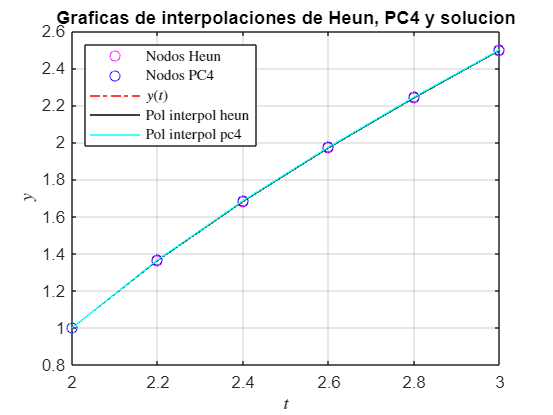


% 4)
% Graficación nodos Heun
x=2:0.2:3;
x1=sol_heun(:,1);
y1=sol_heun(:,2);
x2=sol_pc4(:,1);
y2=sol_pc4(:,2);
Vy=zeros(1, 6);
% obtenemos exactas
for k = 1:6
    Vy(k) = y(sol_heun(k,1));
end
plot(x1, y1, 'mo', ...
     x2, y2, 'bo', ...
     x,  Vy,'r-.', ...
     x,  polyval(pol_interpol_heun,x), 'k-', ...
     x,  polyval(pol_interpol_pc4, x), 'c-', ...
     'Linewidth',0.5)
%axis([1 4 -1 'inf'])
grid on
title('Graficas de interpolaciones de Heun, PC4 y solucion')  % Fórmulas en LaTex
xlabel('$t$', 'Interpreter','latex')
ylabel('$y$', 'Interpreter','latex')
lg=legend('Nodos Heun', 'Nodos PC4','$y(t)$', 'Pol interpol heun','Pol interpol pc4', ...
    'Location','northwest');
set(lg,'Interpreter','latex')

## Problema #2. (10 puntos, 5%)

Resolviendo un problema de valor inicial adecuado, realice una tabla de valores de la funcion de distribucion normal $y(x)$ definida por la integral


$$y(x) = \frac{1}{2} + \frac{1}{\sqrt{2\pi}} \int_{0}^{x} e^{-t^2/2} \, dt$$


para $x \in [0,3]$. 

- (6 pts) Utilice el metodo de Runge-Kutta 4 con paso $h=0.1$para obtener valores aproximados de las imagenes de $y(t_k)$

- (2 pts) Calcule el error relativo al aproximar $y(3)$ por medio del metodo de RK4. Para esto use la funcion $\texttt{integral}$ de Matlab. 

- (2 pts) Calcule el error relativo al aproximar $y(3)$ por medio del metodo de Adams-Bashfort 3. 

**Nota: **Para este problema es util mencionar el **Teorema Fundamental del Calculo**:


$$F(x) = \int_{a}^x f(t) \, dt \Longrightarrow \frac{dF}{dx} = f(x)$$


% Código

y = @(x) 0.5 + 1/(sqrt(2*pi)) * integral(@(t) exp(-t.^2/2), 0, x);
y0 = y(0);

% 1)
% queremos obtener 'y' prima, entonces derivamos y(x) con respecto a x
f = @(t, y) ( (1/(sqrt(2*pi)) ) * ( exp((-t^2)./2) ) );
a = 0; b =3;
% Para que h sea 0.1, necesitamos obtener 
% N => (b-a)/N = h
%       3-0 /N = 0.1
%       N = 30
N=30;
disp('Aqui solucion de RK4')

Aqui solucion de RK4


sol_rk4 = RK4(f,a,b,y0,N)

h = 0.1000

sol_rk4 =          0    0.5000
    0.1000    0.5398
    0.2000    0.5793
    0.3000    0.6179
    0.4000    0.6554
    0.5000    0.6915
    0.6000    0.7257
    0.7000    0.7580
    0.8000    0.7881
    0.9000    0.8159



% veamos las exactas
%for k = 0:5
%    y(k)
%end

% 2) 
disp('Aqui error relativo de RK4')

Aqui error relativo de RK4


err_rel_rk4 = abs( (y(3)) - (sol_rk4(31,2)) ) / abs(y(3))

err_rel_rk4 = 2.7728e-09


% 3)
sol_ab3 = AB3(f,a,b,y0,N)

sol_ab3 =          0    0.5000
    0.1000    0.5398
    0.2000    0.5793
    0.3000    0.6179
    0.4000    0.6554
    0.5000    0.6914
    0.6000    0.7257
    0.7000    0.7580
    0.8000    0.7881
    0.9000    0.8158


disp('Aqui error relativo de AB3')

Aqui error relativo de AB3


err_rel_ab3 = abs( (y(3)) - (sol_ab3(31,2)) ) / abs(y(3))

err_rel_ab3 = 1.6442e-04


format long
disp('Aqui imprimo los siguientes valores y en el siguiente orden:')

Aqui imprimo los siguientes valores y en el siguiente orden:


disp('y(3) en y, rk4 y luego ab3')

y(3) en y, rk4 y luego ab3


y(3)

ans =    0.998650101968370


sol_rk4(31,2)

ans =    0.998650099199294


sol_ab3(31,2)

ans =    0.998485906212153


format default

*Este es un ejemplo que puede servirle... No es parte de los enunciados de la prueba corta. *

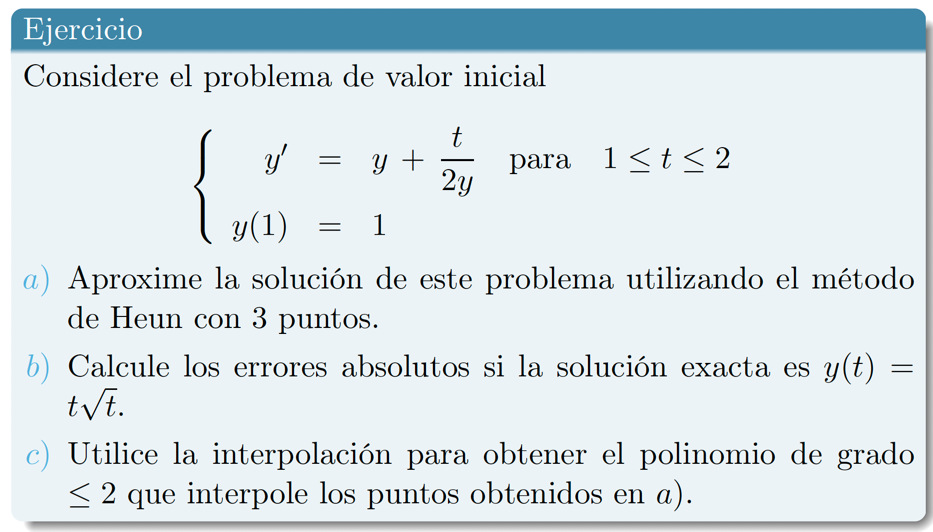

f = @(t,y) y + t./(2.*y);
a = 1; b = 2;
y0 = 1; N = 2; 

% a) 
TablaHeun = Heun(f,a,b,y0,N)

h = 0.5000

TablaHeun =     1.0000    1.0000
    1.5000    1.9196
    2.0000    3.3472



% b) 
y = @(t) t.*sqrt(t); % funcion solucion del PVI
TablaExact = [TablaHeun(:,1), y(TablaHeun(:,1))]

TablaExact =     1.0000    1.0000
    1.5000    1.8371
    2.0000    2.8284



% c) Interpolacion

p = Plagrange(x1, y1)

p =     0.0885   -1.2459    7.1190  -20.7828   32.4696  -20.6560



% Errores absolutos: 
vectorErrAbs = abs(TablaHeun(:,2) - TablaExact(:,2))

vectorErrAbs =          0
    0.0825
    0.5188


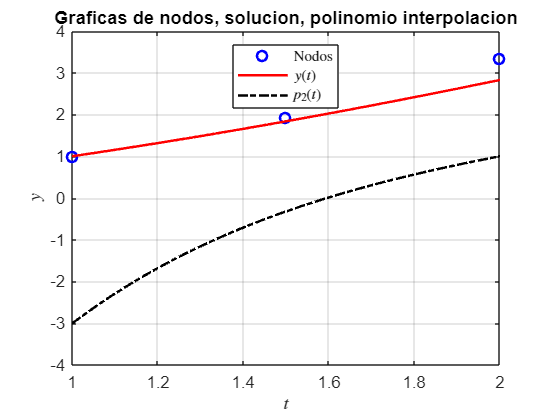


% Grafiquemos

X = linspace(a,b,100);
Y = y(X);

x1 = TablaHeun(:,1);
y1 = TablaHeun(:,2); % nodos

plot(x1, y1, 'bo', X,Y,'r-', X, polyval(p,X), 'k-.','Linewidth',1.5)

grid on
title('Graficas de nodos, solucion, polinomio interpolacion')  % Fórmulas en LaTex
xlabel('$t$', 'Interpreter','latex')
ylabel('$y$', 'Interpreter','latex')
lg=legend('Nodos', '$y(t)$', '$p_2(t)$', ...
    'Location','north');
set(lg,'Interpreter','latex')

# Funciones

***Euler hacia adelante***

function M = Euler(f,a,b,y0,N)
h = (b-a)/N;
M(1,1) = a; M(1,2) = y0;

for i=1:N
    M(i+1,1) = a+i*h;
    M(i+1,2) = M(i,2)+ h*f(M(i,1), M(i,2));
end

end

***Método de Heun - Trapecio explícito***

function M = Heun(f,a,b,y0,N)
h = (b-a)/N
M(1,1) = a; M(1,2) = y0;

for i=1:N
    M(i+1,1) = a+i*h;
    M(i+1,2) = M(i,2)+ h*f(M(i,1), M(i,2));
    M(i+1,2)= M(i,2) + (h/2)*(f(M(i,1), M(i,2)) + f(M(i+1,1), M(i+1,2)));
end

end

***Runge-Kutta 2 (RK2)***

function M = RK2(f,a,b,y0,N)
h = (b-a)/N;
M(1,1) = a; M(1,2) = y0;

for i=1:N
    M(i+1,1) = a+i*h;
    k1 = f(M(i,1), M(i,2));
    k2 = f(M(i,1) + h/2, M(i,2) + (h/2)*k1); 
    M(i+1,2) = M(i,2)+ h*k2;
end
end

***Runge-Kutta 3 (RK3)***

function M = RK3(f,a,b,y0,N)
h = (b-a)/N;
M(1,1) = a; M(1,2) = y0;

for i=1:N
    M(i+1,1) = a+i*h;
    k1 = f(M(i,1), M(i,2));
    k2 = f(M(i,1) + h/2, M(i,2) + (h/2)*k1); 
    k3 = f(M(i+1,1), M(i,2) + h*(2*k2-k1)); 
    M(i+1,2) = M(i,2)+ (h/6)*(k1+4*k2+k3);
end
end

***Runge-Kutta 4 (RK4)***

function M = RK4(f,a,b,y0,N)
h = (b-a)/N
M(1,1) = a; M(1,2) = y0;

for i=1:N
    M(i+1,1) = a+i*h;
    k1 = f(M(i,1), M(i,2));
    k2 = f(M(i,1) + h/2, M(i,2) + (h/2)*k1); 
    k3 = f(M(i,1) + h/2, M(i,2) + (h/2)*k2); 
    k4 = f(M(i+1,1), M(i,2) + h*k3); 
    M(i+1,2) = M(i,2)+ (h/6)*(k1+2*k2+2*k3+k4);
end
end

***Adams-Bashfort 2 pasos (AB2)***

function M = AB2(f,a,b,y0,N)
h = (b-a)/N;
R = RK2(f,a,b,y0,N);    

M(1,1) = a;     M(1,2) = y0;
M(2,1) = a+h;   M(2,2) = R(2,2);


for i = 2:N
    M(i+1,1) = a+i*h;
    M(i+1,2) = M(i,2)+ (h/2)*(3*f(M(i,1), M(i,2))-f(M(i-1,1), M(i-1,2)));
end
end

***Adams-Bashfort 3 pasos (AB3)***

function M = AB3(f,a,b,y0,N)
h = (b-a)/N;
R = RK3(f,a,b,y0,N);  

M(1,1) = a;     M(1,2) = y0;
M(2,1) = a+h;   M(2,2) = R(2,2);
M(3,1) = a+2*h; M(3,2) = R(3,2);


for i = 3:N
    M(i+1,1) = a+i*h;
    M(i+1,2) = M(i,2)+ (h/12)*(23*f(M(i,1), M(i,2))...
        -16*f(M(i-1,1), M(i-1,2))+5*f(M(i-2,1), M(i-2,2)));
end
end

***Adams-Bashfort 4 pasos (AB4)***

function M = AB4(f,a,b,y0,N)
h = (b-a)/N;
R = RK4(f,a,b,y0,N);

M(1,1) = a;     M(1,2) = y0;
M(2,1) = a+h;   M(2,2) = R(2,2);
M(3,1) = a+2*h; M(3,2) = R(3,2);
M(4,1) = a+3*h; M(4,2) = R(4,2);

for i = 4:N
    M(i+1,1) = a+i*h;
    M(i+1,2) = M(i,2)+ (h/24)*( 55*f(M(i,1), M(i,2))...
        -59*f(M(i-1,1), M(i-1,2))+37*f(M(i-2,1), M(i-2,2))...
        -9*f(M(i-3,1), M(i-3,2)) );
end
end


***Adams-Moulton 2 pasos (AM2)***

function M = AM2(f,a,b,y0,N)
h = (b-a)/N;
R = RK4(f,a,b,y0,N);

M(1,1) = a;     M(1,2) = y0;
M(2,1) = a+h;   M(2,2) = R(2,2);

for i = 2:N
    M(i+1,1) = a+i*h;
    M(i+1,2) = M(i,2)+ (h/12)*(5*f(M(i+1,1), R(i+1,2))...
    +8*f(M(i,1), M(i,2))-f(M(i-1,1), M(i-1,2)) );
end

end

***Adams-Moulton 3 pasos (AM3)***

function[M] = AM3(f,a,b,y0,N)
h = (b-a)/N;
R = RK4(f,a,b,y0,N);

M(1,1) = a;     M(1,2) = y0;
M(2,1) = a+h;   M(2,2) = R(2,2);
M(3,1) = a+2*h; M(3,2) = R(3,2);

for i = 3:N
    M(i+1,1) = a+i*h;
    M(i+1,2) = M(i,2)+ (h/24)*( 9*f(M(i+1,1), R(i+1,2))...
    +19*f(M(i,1), M(i,2))-5*f(M(i-1,1), M(i-1,2))...
        + f(M(i-2,1), M(i-2,2)) );
end

end

***PC4***

function M = PC4(f,a,b,y0,N)
h = (b-a)/N;
R = RK4(f,a,b,y0,N);

M(1,1) = a;     M(1,2) = y0;
M(2,1) = a+h;   M(2,2) = R(2,2);
M(3,1) = a+2*h; M(3,2) = R(3,2);
M(4,1) = a+3*h; M(4,2) = R(4,2);

for i = 4:N
    M(i+1,1) = a+i*h;
    M(i+1,2) = M(i,2)+ (h/24)*( 55*f(M(i,1), M(i,2))...
        -59*f(M(i-1,1), M(i-1,2))+37*f(M(i-2,1), M(i-2,2))...
        -9*f(M(i-3,1), M(i-3,2)) );
    
     M(i+1,2) = M(i,2)+ (h/24)*( 9*f(M(i+1,1), M(i+1,2))...
    +19*f(M(i,1), M(i,2))-5*f(M(i-1,1), M(i-1,2))...
        + f(M(i-2,1), M(i-2,2)) );
end

end

***Polinomios cardinales de Lagrange***

function c = Lk(k,x)

m = length(x);
c = 1;

for i = [1:k-1, k+1:m]
    c = conv(c, [1/(x(k)-x(i)), -x(i)/(x(k)-x(i))]);
end

end

***Polinomio interpolador de Lagrange***

function p = Plagrange(x, y)

n = length(x);
p = 0;

for k = 1:n
    p = p + y(k)*Lk(k, x);
end

end